%asd
s=tf("s");
% Q=
% P=
% figure(1)
% rlocus(Q/P)
% 
% hold on
% p = rlocos(Q/P, 6)
% plot(real(p), imag(p), 'rx', 'MarkerSize', 10)

% 3.22 a
G = (0.2)/((s^2+s+1) * (s+0.2))

G =
 
              0.2
  ---------------------------
  s^3 + 1.2 s^2 + 1.2 s + 0.2
 
Continuous-time transfer function.



Q = 0.2;
P = ((s^2+s+1) * (s+0.2))

P =
 
  s^3 + 1.2 s^2 + 1.2 s + 0.2
 
Continuous-time transfer function.



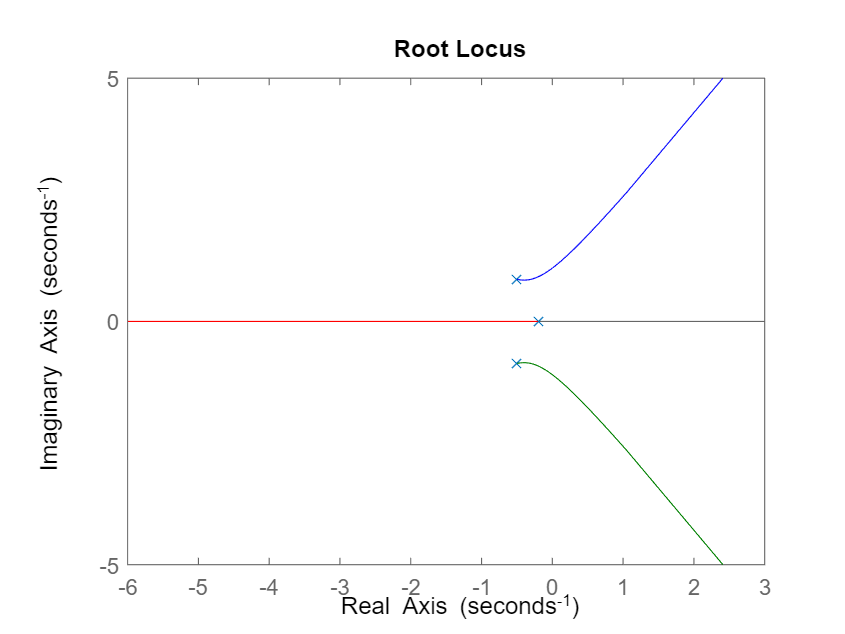

figure(1)
rlocus(Q/P)

%figure(2)
%plot(real(p1), imag(p1), "rx", "MarkerSize",10)
%PQ formelen ger generellt svar bozo (b+-sqrt(b^2-4ac))/2*a     geddit P Q

%bad when 6.2
Kp = 6.1

Kp = 6.1000

Gf = feedback(Kp * G,1)

Gf =
 
              1.22
  ----------------------------
  s^3 + 1.2 s^2 + 1.2 s + 1.42
 
Continuous-time transfer function.



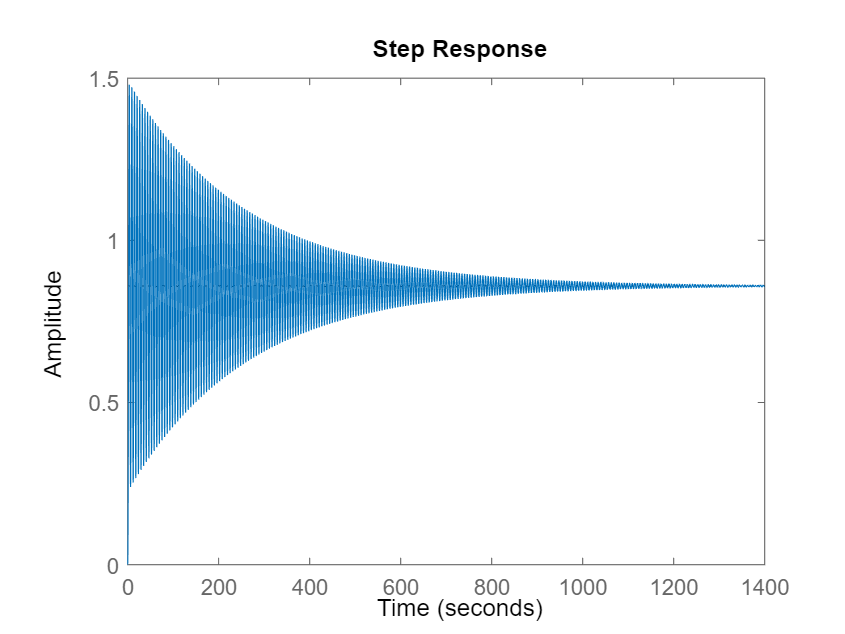

step(Gf)

% 3.22 b
clf
Kp = 1

Kp = 1

Ki = 1.4

Ki = 1.4000

F = Kp + Ki/s

F =
 
  s + 1.4
  -------
     s
 
Continuous-time transfer function.



P = s*(s^2+s+1) * (s+0.2)+0.2*s

P =
 
  s^4 + 1.2 s^3 + 1.2 s^2 + 0.4 s
 
Continuous-time transfer function.



Q = 0.2

Q = 0.2000

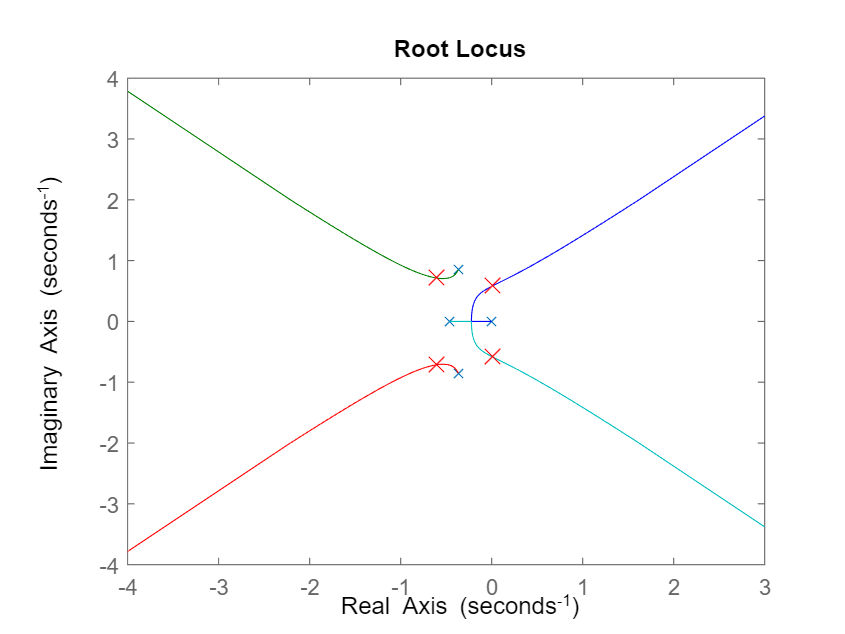

figure
rlocus(Q/P);
hold on
p = rlocus(Q/P, 1.5);
plot(real(p), imag(p), 'rx', 'MarkerSize', 10);

clf
Gf = feedback(F * (Q/P),1)

Gf =
 
                    0.2 s + 0.28
  ------------------------------------------------
  s^5 + 1.2 s^4 + 1.2 s^3 + 0.4 s^2 + 0.2 s + 0.28
 
Continuous-time transfer function.



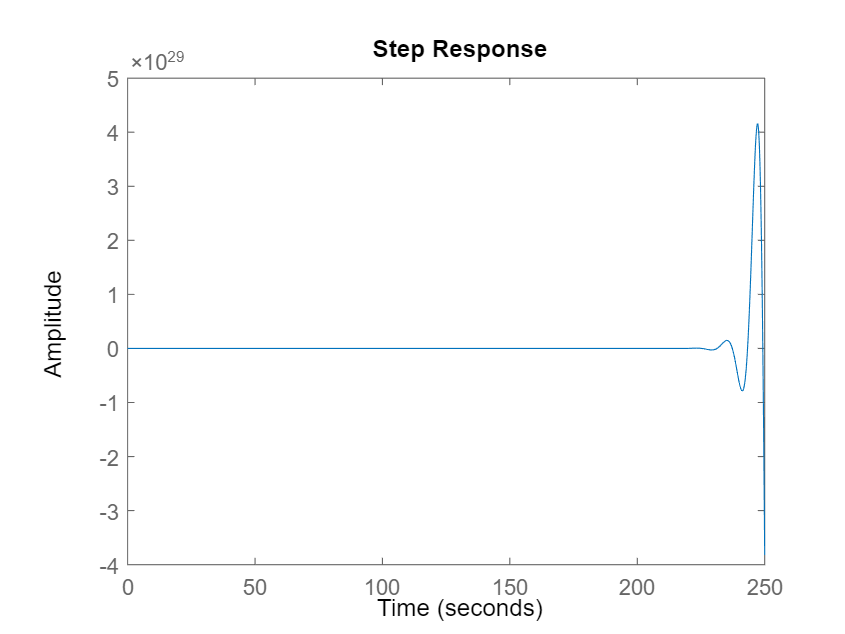

step(Gf)

% 3.22 c
Kp = 1;
Ki = 1;
T = 0.1;
Kd = 1

Kd = 1

F = Kp + Ki/s + (Kd*s)/(s*T+1)

F =
 
  1.1 s^2 + 1.1 s + 1
  -------------------
      0.1 s^2 + s
 
Continuous-time transfer function.




P = (0.1*s+1)*(s^4+1.2*s^3+1.2*s^2+0.4*s+0.2)

P =
 
  0.1 s^5 + 1.12 s^4 + 1.32 s^3 + 1.24 s^2 + 0.42 s + 0.2
 
Continuous-time transfer function.



Q = 0.2*s^2

Q =
 
  0.2 s^2
 
Continuous-time transfer function.



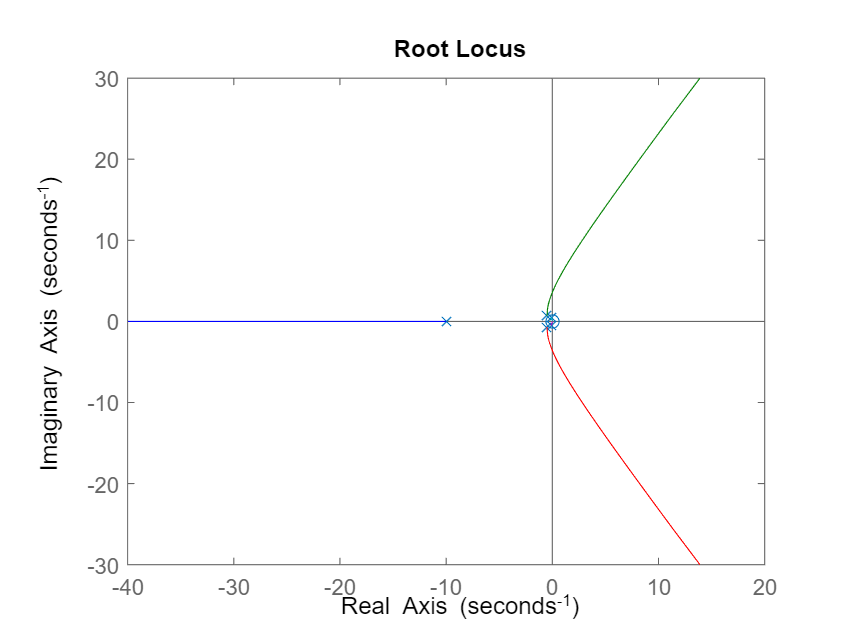

figure
rlocus(Q/P);
hold on

%p = rlocus(Q/P, 5000);
%plot(real(p), imag(p), 'rx', 'MarkerSize', 10);


%3.10 

G1 = 1/((s+1)*(s-1)*(s+5))

G1 =
 
           1
  -------------------
  s^3 + 5 s^2 - s - 5
 
Continuous-time transfer function.



Kp1 = 1

Kp1 = 1

F = Kp1 

F = 1

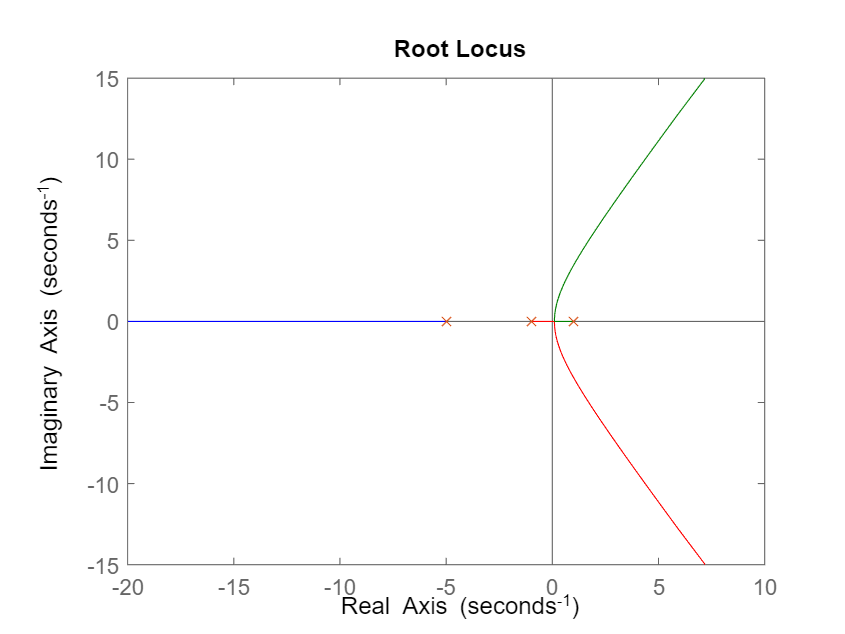


figure
hold on

rlocus(G1);
rlocus(G1, 10);


%b


Kd1 = 0.1;
P1 = ((s+1)*(s-1)*(s+5))

P1 =
 
  s^3 + 5 s^2 - s - 5
 
Continuous-time transfer function.



Q1 = 0.5*s + 1

Q1 =
 
  0.5 s + 1
 
Continuous-time transfer function.



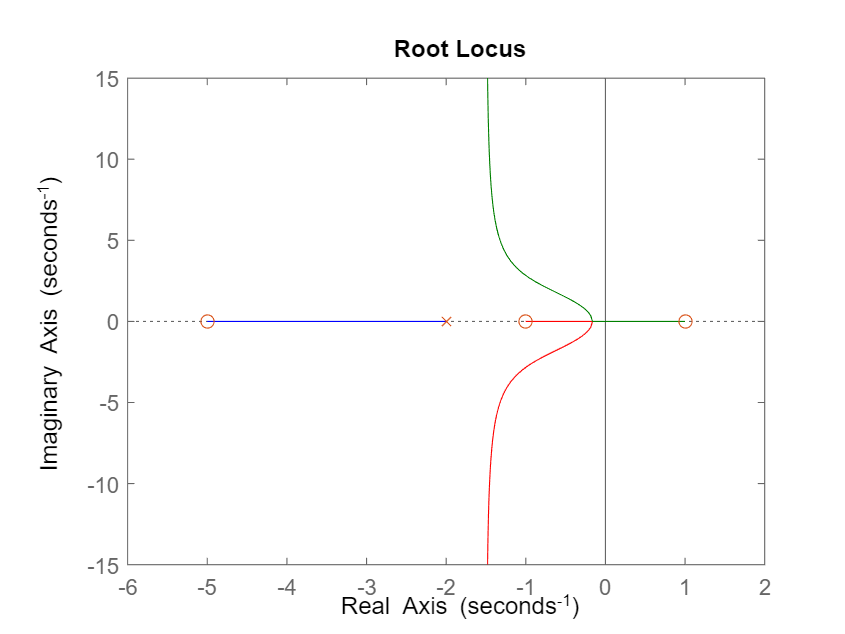

figure
hold on

rlocus(P1/Q1);
rlocus(P1/Q1, Kd1);